% add Psort_read_psort() function to path
path = 'C:\Users\baozi\OneDrive - Johns Hopkins\Documents\JHU\CullenLab_new\CSsorting\osfstorage-archive';
addpath([path '\Psort_matlab_codes']);

% load all macaque file name
load([path '\pCell_properties\Macaque_Neural_Properties.mat']);

fs = 50000;
fs_ms = fs/1000;
pre_ms = 1;
post_ms = 10;

all_ss_waveform = cell(length(Macaque_Neural_Properties.name),1);
all_cs_waveform = cell(length(Macaque_Neural_Properties.name),1);
for i_file = 1:length(Macaque_Neural_Properties.name)
    filename = Macaque_Neural_Properties.name{i_file};
    display(['Loading ' filename]);
    psortDataBase = Psort_read_psort([path '\macaque_3min_psort_data\' filename '.psort']);

    % get ss and cs index
    ss_index = find(psortDataBase.topLevel_data.ss_index);
    cs_index = find(psortDataBase.topLevel_data.cs_index);

    % file 27 has cs_index shift
    if i_file ==27
        cs_index = cs_index + 22;
    end
    
    % get all waveform
    all_ss_waveform{i_file} = [];
    reshuffle = randperm(length(ss_index));
    ss_count = 0;
    ii = 0;
    while ss_count < 1000
        ii = ii + 1;
        i = reshuffle(ii);
        if ss_index(i)-pre_ms*fs_ms < 1
            continue
        end
        if ss_index(i)+post_ms*fs_ms > length(psortDataBase.topLevel_data.ch_data)
            continue
        end
        all_ss_waveform{i_file} = [all_ss_waveform{i_file},psortDataBase.topLevel_data.ch_data(ss_index(i)-pre_ms*fs_ms:ss_index(i)+post_ms*fs_ms)];
        ss_count = ss_count + 1;
    end
    
    all_cs_waveform{i_file} = [];
    for i = 1:length(cs_index)
        if cs_index(i)-pre_ms*fs_ms < 1
            continue
        end
        if cs_index(i)+post_ms*fs_ms > length(psortDataBase.topLevel_data.ch_data)
            continue
        end
        all_cs_waveform{i_file} = [all_cs_waveform{i_file},psortDataBase.topLevel_data.ch_data(cs_index(i)-pre_ms*fs_ms:cs_index(i)+post_ms*fs_ms)];
    end
    display(['Finish ' filename]);
end

Loading B091608_1218_Adapt_sorted_MAF


Finish B091608_1218_Adapt_sorted_MAF


Loading B091707_1414_List_sorted_MAF


Finish B091707_1414_List_sorted_MAF


Loading B091908_1_1509_Adapt_sorted_MAF


Finish B091908_1_1509_Adapt_sorted_MAF


Loading B091908_21602_Adapt_sorted_MAF


Finish B091908_21602_Adapt_sorted_MAF


Loading B093008_1242_AdaptForward_sorted_MAF


Finish B093008_1242_AdaptForward_sorted_MAF


Loading B100308_2_1412_Adapt_sorted_MAF


Finish B100308_2_1412_Adapt_sorted_MAF


Loading B110807_1632_List_sorted_MAF


Finish B110807_1632_List_sorted_MAF


Loading B111507_1528_List_sorted_MAF


Finish B111507_1528_List_sorted_MAF


Loading B121407_1_1124_List_sorted_MAF


Finish B121407_1_1124_List_sorted_MAF


Loading F090606_1325_Adapt_sorted_MAF


Finish F090606_1325_Adapt_sorted_MAF


Loading F091106_1002_Adapt_sorted_MAF


Finish F091106_1002_Adapt_sorted_MAF


Loading F100906_1343_List_sorted_MAF


Finish F100906_1343_List_sorted_MAF


Loading F101106_1324_Adapt_sorted_MAF


Finish F101106_1324_Adapt_sorted_MAF


Loading F101606_1308_List_sorted_MAF


Finish F101606_1308_List_sorted_MAF


Loading F102006_0933_Adapt_sorted_MAF


Finish F102006_0933_Adapt_sorted_MAF


Loading F102506_1518_Adapt_sorted_MAF


Finish F102506_1518_Adapt_sorted_MAF


Loading F102706_1449_Adapt_sorted_MAF


Finish F102706_1449_Adapt_sorted_MAF


Loading F110206_1411_Adapt_sorted_MAF


Finish F110206_1411_Adapt_sorted_MAF


Loading F110706_1421_Adapt_sorted_MAF


Finish F110706_1421_Adapt_sorted_MAF


Loading F112006_1501_Adapt_sorted_MAF


Finish F112006_1501_Adapt_sorted_MAF


Loading K10_1_directionaltest_sorted_MAF


Finish K10_1_directionaltest_sorted_MAF


Loading K14_1_directionaltest_sorted_MAF


Finish K14_1_directionaltest_sorted_MAF


Loading K16_2_directionaltest_sorted_MAF


Finish K16_2_directionaltest_sorted_MAF


Loading K21_2_directionaltest_sorted_MAF


Finish K21_2_directionaltest_sorted_MAF


Loading K25_1dirtuning_sorted_MAF


Finish K25_1dirtuning_sorted_MAF


Loading K26_1dirtuning_sorted_MAF


Finish K26_1dirtuning_sorted_MAF


Loading K32_1dirtest_sorted_MAF


Finish K32_1dirtest_sorted_MAF


Loading K33_1dirtest_sorted_MAF


Finish K33_1dirtest_sorted_MAF


Loading K33_2dirtest_sorted_MAF


Finish K33_2dirtest_sorted_MAF


Loading K34_1dirtest_sorted_MAF


Finish K34_1dirtest_sorted_MAF


Loading K38_1_DirectionalTest_sorted_MAF


Finish K38_1_DirectionalTest_sorted_MAF


Loading K40_1_Dirtuning_sorted_MAF


Finish K40_1_Dirtuning_sorted_MAF


Loading K42_1_ErrorDirTest_sorted_MAF


Finish K42_1_ErrorDirTest_sorted_MAF


Loading K45_1_ErrorDirectionTest_sorted_MAF


Finish K45_1_ErrorDirectionTest_sorted_MAF


Loading K48_1_CSddirTuning_sorted_MAF


Finish K48_1_CSddirTuning_sorted_MAF


Loading K48_2_CSddirTuning_sorted_MAF


Finish K48_2_CSddirTuning_sorted_MAF


Loading K50_2_directionaltest_sorted_MAF


Finish K50_2_directionaltest_sorted_MAF


Loading K55_1_DirectionalTest_sorted_MAF


Finish K55_1_DirectionalTest_sorted_MAF


Loading K57_1_CSdir_tuning_sorted_MAF


Finish K57_1_CSdir_tuning_sorted_MAF


Loading K57_2_CSdirtuning_sorted_MAF


Finish K57_2_CSdirtuning_sorted_MAF


Loading K60_1_CSdirtuning_sorted_MAF


Finish K60_1_CSdirtuning_sorted_MAF


Loading K60_2_CSdirtuning_sorted_MAF


Finish K60_2_CSdirtuning_sorted_MAF


Loading K69_1_DirTuning_sorted_MAF


Finish K69_1_DirTuning_sorted_MAF


Loading P03_2_pre_A_sorted_MAF


Finish P03_2_pre_A_sorted_MAF


Loading S18_1_DirectionalTuning_leveltrigger_sorted_MAF


Finish S18_1_DirectionalTuning_leveltrigger_sorted_MAF


Loading S27_1_HorzErrorSizetest_sorted_MAF


Finish S27_1_HorzErrorSizetest_sorted_MAF


Loading S34_1_directionaltuning_sorted_MAF


Finish S34_1_directionaltuning_sorted_MAF


Loading S36_1_directionaltuning_sorted_MAF


Finish S36_1_directionaltuning_sorted_MAF


Loading S38_1_directionaltuning_sorted_MAF


Finish S38_1_directionaltuning_sorted_MAF


Loading W091008_1248_Adapt_sorted_MAF


Finish W091008_1248_Adapt_sorted_MAF


Loading W091208_1348_Adapt_sorted_MAF


Finish W091208_1348_Adapt_sorted_MAF


Loading W111308_1604_Adapt_sorted_MAF


Finish W111308_1604_Adapt_sorted_MAF


Loading W120108_1622_List_sorted_MAF


Finish W120108_1622_List_sorted_MAF


Loading W120208_1_1428_Adapt_sorted_MAF


Finish W120208_1_1428_Adapt_sorted_MAF


Loading W120308_2_1622_Adapt_sorted_MAF


Finish W120308_2_1622_Adapt_sorted_MAF


Loading W120508_1_1420_List_sorted_MAF


Finish W120508_1_1420_List_sorted_MAF


Loading W120508_2_1548_Adapt_sorted_MAF


Finish W120508_2_1548_Adapt_sorted_MAF


save([path '\all_cs_waveform.mat'],'all_cs_waveform');
% load([path '\all_cs_waveform.mat']);
save([path '\all_ss_waveform.mat'],'all_ss_waveform');
% load([path '\all_ss_waveform.mat']);

% get whole test data
test_whole_data = cell(1,4);
for i = 1:4
    i_file = i + 53;
    filename = Macaque_Neural_Properties.name{i_file};
    display(['Loading ' filename]);
    psortDataBase = Psort_read_psort([path '\macaque_3min_psort_data\' filename '.psort']);
    test_whole_data{i} = psortDataBase.topLevel_data.ch_data;
end
save([path '\test_whole_data.mat'],'test_whole_data');

% get std for each file
std_data = zeros(1,57);
for i_file = 1:57
    filename = Macaque_Neural_Properties.name{i_file};
    display(['Loading ' filename]);
    psortDataBase = Psort_read_psort([path '\macaque_3min_psort_data\' filename '.psort']);
    std_data(i_file) = std(psortDataBase.topLevel_data.ch_data,0);
end
save([path '\std_data.mat'],'std_data');

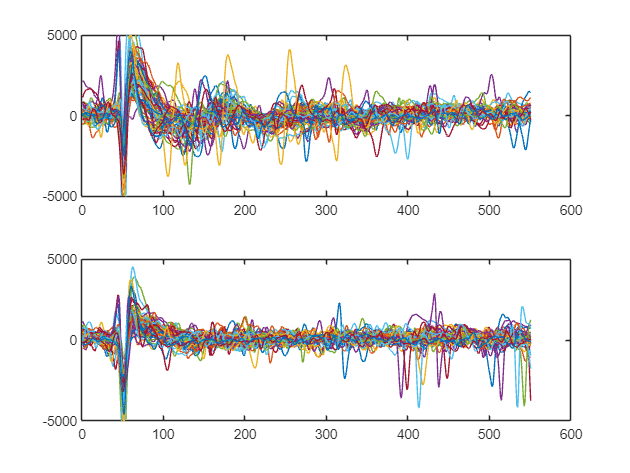

figure;
for i = 1:length(all_cs_waveform)
    subplot(211);
    plot(all_cs_waveform{i}(:,1));
    hold on;
    ylim([-5000,5000]);
    subplot(212);
    plot(all_ss_waveform{i}(:,1));
    hold on;
    ylim([-5000,5000]);
end

% cs
for i = 1:length(all_cs_waveform)
    if mod(i,5) == 1
        figure;
        sgtitle([num2str(i) '~' num2str(i+4)]);
    end
    row = mod(i-1,5)+1;
    subplot(5,4,4*(row-1)+1);
    plot(all_cs_waveform{i},'k');
    xticks([]);
    yticks([]);
    subplot(5,4,4*(row-1)+2);
    plot(diff(all_cs_waveform{i},[],1),'k');
    xticks([]);
    yticks([]);
    subplot(5,4,4*(row-1)+3);
    plot(all_ss_waveform{i},'k');
    xticks([]);
    yticks([]);
    subplot(5,4,4*(row-1)+4);
    plot(diff(all_ss_waveform{i},[],1),'k');
    xticks([]);
    yticks([]);
end

figure;
disp_time = [-pre_ms*fs_ms:post_ms*fs_ms]/fs_ms;
for i = 1:5
    row = mod(i-1,5)+1;
    subplot(5,2,2*(row-1)+1);
    plot(disp_time,all_cs_waveform{i+22},'k');
    hold on;
    plot(disp_time,mean(all_cs_waveform{i+22},2),'r');
    if (row ~= 5)
        xticks([]);
    end
    yticks([]);
    xlim([-pre_ms,post_ms]);
    ylim([-6000,6000]);

    subplot(5,2,2*(row-1)+2);
    plot(disp_time,all_ss_waveform{i+22},'k');
    hold on;
    plot(disp_time,mean(all_ss_waveform{i+22},2),'r');
    if (row ~= 5)
        xticks([]);
    end
    yticks([]);
    xlim([-pre_ms,post_ms]);
    ylim([-6000,6000]);

end
subplot(5,2,1);
title('Complex spike');
subplot(5,2,2);
title('Simple spike');
for i = 1:5
    subplot(5,2,2*i-1);
    ylabel(['Cell ' num2str(i)]);
end
subplot(5,2,9);
xlabel('Time (ms)');
subplot(5,2,10);
xlabel('Time (ms)');